# Principal Component Analysis with SVD

## Introduction

Recent studies of The Tropics region across a broad range of social and economic indicators

([https://www.jcu.edu.au/state-of-the-tropics/publications/2014/2014-report/State-of-the-Tropics-2014-Full-Report.pdf](https://www.jcu.edu.au/state-of-the-tropics/publications/2014/2014-report/State-of-the-Tropics-2014-Full-Report.pdf)) indicate that it becomes prominent as a critical global region with a distinctive set of opportunities. It covers only 40% of the world’s surface area and it is a home to 40% of the world’s adult population and 55% of the world’s children population under the age of five. The Tropic’s economy is growing 20% faster than the Rest of the World but still more than two-thirds of the world’s poorest people live in the Tropics. Significant poverty reduction is observed in South East Asia and Central America. Persistently with the higher levels of poverty, more people experience undernourishment, even though the undernourishment rate in the Tropics has declined by one-third over the past two decades. The urbanization rate has increased from 31% to 45% in 2010. Life expectancy has also increased across all regions of the Tropics and there is a significant decrease in maternal and child mortality rates since 1950. Mean years of schooling of adults has almost doubled in the Tropics since 1980, adult literacy rates have increased faster in the Tropics than the Rest of the World and youth literacy rates have increased in all regions of the Tropics except in Oceania since 1990, but still steadily lower than the Rest of the World.

In current study, the social and economic indicators listed in (Table 1) are subjected to Principal Component Analysis (PCA) with SVD (Singular Value Decomposition). Principal component analysis as a variable reduction procedure is appropriate when we have obtained data on a number of observed variables and believe that there is some redundancy among the variables. Therefore, we wish to develop a smaller number of artificial variables (called principal components) that will account for most of the variance in the observed variables that may be used as criterion variables in subsequent analyses. The first component extracted accounts for a maximal amount of total variance in the observed variables. The second component will have two important features: a) it accounts for a maximal amount of variance in the data set that was not accounted for by the first component and it will be correlated with some of the variables that did not display strong correlations with the first component; b) second feature is that it will be uncorrelated with the first component.  

PCA is connected to SVD that is a highly robust method because of its ability to decompose any matrix into UΣVTresulting with two orthogonal matrices U and V and diagonal Σ. Nevertheless, in this study, SVD is applied on the matrix of observations by decomposing the data matrix into three factors that contain the eigenvectors and eigenvalues utilized in the PCA method. The study demonstrates the interpretative power of PCA with SVD by carrying out an exploratory data analysis with final goal to determine relationships that exist between and within the data structure of a statistical data from The Tropics. 

## Data

The dataset of interest, called SotTCombined2010, is retrieved from the State of the Tropics website located at the following URL: [https://www.jcu.edu.au/state-of-the-tropics](https://www.jcu.edu.au/state-of-the-tropics). It is available as spreadsheet in MS Excel®  (.xlsx) extracted from various existing data sources for a period of 2010, such as: FAO database ([http://www.fao.org/faostat/en/#data](http://www.fao.org/faostat/en/#data)); KILM database ([http://kilm.ilo.org/kilmnet/](http://kilm.ilo.org/kilmnet/)); Barro and Lee Educational Attainment dataset ([http://www.barrolee.com/](http://www.barrolee.com/)); Povcal Net, World Bank database ([http://iresearch.worldbank.org/PovcalNet/povOnDemand.aspx](http://iresearch.worldbank.org/PovcalNet/povOnDemand.aspx)); WHO Global TB database  ([http://www.who.int/tb/country/global_tb_database](http://www.who.int/tb/country/global_tb_database)) and etc.. 

***Size of the dataset****:* The size of the dataset is 109 rows. It consists of 14 variables as shown in Table 1. 

% Create table from.xls  
T = readtable('Data_Description.xls','ReadRowNames',true)

T = 14×3 table
                     VariableName                 DataType                                    Description                             
          __________________________________    _____________    _____________________________________________________________________

    1     {'Country'                       }    {'Character'}    {'Name of the countries involved in the research'                   }
    2     {'Life Expectancy (years)'       }    {'Numeric'  }    {'Calculated average of life expectancy in years'                   }
    3     {'Poverty under $1.25 per day'   }    {'Numeric'  }    {'Extreme poverty measure for developing nations'                   }
    4     {'Population under 15'           }    {'Numeric'  }    {'Total population under 15 years of age in each country'           }
    

Table 1: Data description of the SotTCombined2010 dataset consisting of one categorical/character variable and thirteen numeric/continuous variables.

 ***Importing the dataset***

% Import raw data from excel file
Xshift = xlsread('SotTCombined2010.xlsx')

Xshift = 	1.0e+06 *

    0.0000    0.0000    0.0093    0.0001       NaN    0.0000       NaN    0.0580    0.0002    0.0000    0.0000    0.0001    0.0584
    0.0001    0.0000    0.0041    0.0000    0.0000    0.0000    0.0001    0.0061    0.0001    0.0000    0.0000    0.0000    0.0034
    0.0000    0.0000    0.0007    0.0001    0.0000    0.0000    0.0001    0.0100    0.0001    0.0000    0.0000    0.0001    0.0259
    0.0001    0.0000    0.0071    0.0000       NaN    0.0000    0.0000    0.0095    0.0002    0.0000    0.0000    0.0000    0.0121
    0.0001    0.0000    0.0041    0.0001    0.0000    0.0000    0.0001    0.0120    0.0002    0.0000    0.0000    0.0000    0.0023
    0.0001    0.0000    0.0090    0.0001    0.0000    0.0000    0.0001    0.0540    0.0001    0.0000    0.0000    0.0001    0.0096
    0.0001    0.0000    0.0002    0.0001       NaN    0.0000    0.0001    0.0007    0.0000    0.0000       NaN    0.0001    0.0001
    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000  

We call raw data matrix Xshift, a rectangular matrix with size (109x13), imported from excel file (SotTCombined2010.xlsx) with *xlsread()* code into MatLab environment where number of columns/measured variables is presented by n, (n=13) and the number of row or “cases” which have had all variables measured is presented by m, (m=109). The code, *xlsread(*[*filename*](https://www.mathworks.com/help/matlab/ref/xlsread.html#btg5vmt-1-filename)*)* reads the first worksheet in the MS Excel® spreadsheet workbook named filename and returns only the numeric data in a matrix. As a result, the categorical variable “Country” is omitted.

***Pre-processing the dataset***

*Excluding countries with missing values*

% Are there missing valuesin the dataset? 1 = true
missing = ismissing(Xshift)

missing = 109×13 logical array
   0   0   0   0   1   0   1   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   1   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   1   0   0   0   0   0   1   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   1   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0


% Total number of missing values
totalNum = sum(sum(isnan(Xshift),2))

totalNum = 187

% Number of missing values per column
Num = sum(isnan(Xshift))

Num =      0    32     5    21    35    19    24     0     0    32    17     0     2


% Total number of columns containing missing values
column = sum(any(isnan(Xshift),1))

column = 9

% Number of missing values per row
row = sum(isnan(Xshift),2)

row =      2
     0
     0
     1
     0
     0
     2
     0
     1
     0


% Total number of rows containing missing values
row = sum(row>0)

row = 53

% Remove missing values using rmmissing() function
Xshiftrm = rmmissing(Xshift)

Xshiftrm = 	1.0e+06 *

    0.0001    0.0000    0.0041    0.0000    0.0000    0.0000    0.0001    0.0061    0.0001    0.0000    0.0000    0.0000    0.0034
    0.0000    0.0000    0.0007    0.0001    0.0000    0.0000    0.0001    0.0100    0.0001    0.0000    0.0000    0.0001    0.0259
    0.0001    0.0000    0.0041    0.0001    0.0000    0.0000    0.0001    0.0120    0.0002    0.0000    0.0000    0.0000    0.0023
    0.0001    0.0000    0.0090    0.0001    0.0000    0.0000    0.0001    0.0540    0.0001    0.0000    0.0000    0.0001    0.0096
    0.0000    0.0000    0.0018    0.0001    0.0000    0.0000    0.0001    0.0190    0.0002    0.0000    0.0000    0.0000    0.0051
    0.0000    0.0000    0.0283    0.0001    0.0000    0.0000    0.0001    0.2200    0.0002    0.0000    0.0000    0.0000    0.0258
    0.0000    0.0000    0.0079    0.0001    0.0000    0.0000    0.0001    0.0380    0.0001    0.0000    0.0000    0.0001    0.0205
    0.0001    0.0000    0.0006    0.0001    0.0000    0.0000

Under the circumstances described, exactly 187 missing values or “NaN” distributed in 9 columns and 53 rows are removed with *rmissing ()* code resulting into reduced matrix size of a newly created matrix called Xshiftrm (56x13).  

***Creating, centering and scaling matrix of raw data for PCA***

PCA only deals with a square matrix containing only numeric data, but SVD can deal with a rectangular matrix. In general, we use SVD to perform PCA, but before applying the SVD, 

we need to pre-process the data table by mean-centering the data. Primarily, computing the mean row vector and the variance row vector for all data vectors is performed with the following code expressions in Matlab:

% Compute means and variance of each column
colmeans = mean(Xshiftrm,1)

colmeans = 	1.0e+04 *

    0.0064    0.0000    1.3266    0.0077    0.0006    0.0000    0.0086    7.0307    0.0068    0.0000    0.0000    0.0046    2.1816


colvars = var(Xshiftrm,1)

colvars = 	1.0e+10 *

    0.0000    0.0000    0.0847    0.0000    0.0000    0.0000    0.0000    3.4232    0.0000    0.0000    0.0000    0.0000    0.1227


Therefore, subtracting the mean row vector from all the data vectors and dividing by the square root of the variance vector to avoid bias caused by large variations among variables resulted 

into creation of a new matrix called X-scaled matrix (56x13).

% Compute the X-scaled matrix from the raw data with removed missing values
X_scaled = (Xshiftrm - repmat(colmeans, size(Xshiftrm,1), 1)) ./ repmat(sqrt(colvars), size(Xshiftrm,1), 1)

X_scaled =    -0.6533    0.7658   -0.3140   -2.0965   -1.1657   -1.0432   -2.2527   -0.3470    1.0354    1.0569   -0.8305   -0.0649   -0.5260
   -1.9365   -0.5003   -0.4327    0.4453    1.2828    1.4238    0.6716   -0.3260   -0.3813   -0.4782    0.5615    0.7461    0.1155
   -1.4096    2.2273   -0.3165   -0.5996   -1.4038   -0.1775   -0.6138   -0.3151    1.7833    1.7432    3.7602   -1.6956   -0.5580
   -1.2549   -0.6691   -0.1482   -0.3871   -0.0017   -0.4966   -0.2097   -0.0881    1.3482   -0.4174   -0.2962    0.2870   -0.3487
   -1.9454    1.5105   -0.3951   -1.2737   -1.0338   -0.1848   -1.5149   -0.2773    2.2462    1.2928    0.7091   -0.3273   -0.4778
   -1.7450    2.4411    0.5158   -0.6214   -1.0625   -0.2147   -1.5258    0.8091    2.7181    1.7807    2.1255   -0.5758    0.1126
   -1.6968   -0.1189   -0.1832   -1.2628   -0.7426   -0.5408   -1.3801   -0.1746    1.1754    0.0941    0.1045    0.2406   -0.0376
   -0.3109   -1.0295   -0.4352    0.6815    0.6917    1.3652    0.8522  

X-scaled matrix contains variables that are standardized so that each variable has a mean of zero and a variance of one. The total variance in the data set is the sum of variances of all observed variables. Now, because each variable has a variance of one, it contributes only one unit of variance to the total variance in the data set. As a result, the total variance in PCA will always be equal to the number of variables being analysed. For example, we have 13 variables available in the current study, the total variance will always equals to 13. The PCA components that are going to be created will always partition total variance. 

## Methods and Analysis

***Perform PCA using Singular Value Decomposition (SVD)***

The most essential step is performing SVD. As one of the most important linear algebra principles, SVD is utilized to calculate a lower dimensional space of PCA. The aim of the SVD method is to diagonalize the data matrix X_scaled (56x13) into three matrices: U, S and V. In general, U(56x56) matrix represents left singular vectors, S(56x13) is a diagonal matrix comprised of singular values that are sorted from highest-to-lowest and must satisfy the rule that the first singular value is the largest and each succeeding singular value are smaller: 

σ1 > σ2> σ3 >  σ4  > σ5 >………> σn

And V (13x13) stands for right singular vectors, the non-zero eigenvectors or the principal components of the PCA space. The left and right singular matrices, i.e. U and V, are orthogonal matrices. From the calculated matrices U, S and V, we can notice that the first singular value of S matrix was more than the second one, thus, the first column of V represents the first principal component and so on. 

% Compute Singular Value Decomposition that is equivalent to X_scaled = U*S*V'
[U,S,V] = svd(X_scaled)

U =    -0.1557    0.0538    0.1721   -0.2918   -0.0234   -0.0794    0.0126   -0.1347    0.0252   -0.0194   -0.0340   -0.0717    0.0481   -0.1909   -0.0240   -0.0393   -0.0878   -0.1967   -0.0144   -0.2464   -0.1796   -0.1929   -0.1037    0.0339    0.0780   -0.0700   -0.0547    0.2521    0.0786    0.0555    0.2086    0.1366    0.1466    0.0878    0.0870    0.1411    0.2041    0.1527   -0.1914   -0.0008    0.0359    0.1692    0.0731    0.2034    0.0791    0.1378    0.2263    0.1276    0.0133   -0.0036
    0.0361    0.0625   -0.2533    0.0890    0.0461   -0.1820   -0.2519    0.0986    0.1385   -0.4488   -0.3670    0.0393    0.0041   -0.1361   -0.0252    0.0491    0.0036   -0.1223   -0.1351   -0.0135    0.2793    0.2993    0.0843   -0.0409   -0.0061    0.1696    0.1380    0.1093    0.0447    0.1683    0.0647    0.0420    0.0343   -0.0899   -0.0170   -0.0510    0.1658    0.0390    0.0175    0.0332   -0.0597    0.1320   -0.0585   -0.0345    0.0617    0.0291    0.0683    0.1197   -0.0988   -0

S =    18.7152         0         0         0         0         0         0         0         0         0         0         0         0
         0   11.4672         0         0         0         0         0         0         0         0         0         0         0
         0         0    8.2715         0         0         0         0         0         0         0         0         0         0
         0         0         0    7.5886         0         0         0         0         0         0         0         0         0
         0         0         0         0    5.8351         0         0         0         0         0         0         0         0
         0         0         0         0         0    5.4528         0         0         0         0         0         0         0
         0         0         0         0         0         0    4.5567         0         0         0         0         0         0
         0         0         0         0         0         0         0    3.913

V =     0.3421   -0.0551    0.2105   -0.0248   -0.1184    0.2813    0.5508   -0.2349    0.1109    0.4655    0.3810   -0.0848   -0.0445
   -0.3579   -0.0097   -0.0040    0.2234    0.2099   -0.1617    0.2667   -0.4635   -0.2524    0.0865   -0.0544    0.6198   -0.0865
   -0.0095   -0.6408    0.0490    0.0379   -0.1113   -0.1692    0.0240    0.0747    0.0593    0.0453    0.0332    0.1310    0.7172
    0.3425   -0.0146   -0.0855    0.4106    0.1209    0.0438   -0.0697    0.0185   -0.4745    0.3941   -0.5003   -0.2173    0.0824
    0.3246    0.0453   -0.0445    0.2629    0.1439   -0.3738   -0.4248   -0.4719    0.4796    0.1029    0.1263   -0.0333   -0.0145
   -0.0042    0.0839   -0.7949    0.0603   -0.5701   -0.0514    0.1202   -0.1051    0.0059    0.0413    0.0372    0.0244    0.0231
    0.3427   -0.0494   -0.0899    0.4102    0.1234    0.0227   -0.0185    0.1973   -0.3549   -0.4211    0.5723    0.1267   -0.0442
   -0.0354   -0.6156    0.0857    0.1146   -0.2249   -0.2693    0.0240    0.139

***Identifying relationships between the variables described by the 1st principal component vector***

% Creating a table that summarizes the PCA/SVD loadings
T = readtable('PCA_SVD.xls','ReadRowNames',true)

T = 13×3 table
                      VariableName               x1stPCAVector    x2ndPCAVector
           __________________________________    _____________    _____________

    v1     {'Life Expectancy (years)'       }        0.3421          -0.0551   
    v2     {'Poverty under $1.25 per day'   }       -0.3579          -0.0097   
    v3     {'Population under 15'           }       -0.0095          -0.6408   
    v4     {'Adult literacy (% above 15)'   }        0.3425          -0.0146   
    v5     {'Mean years of schooling'       }        0.3246           0.0453   
    v6     {'Unemployment (%)'              }       -0.0042           0.0839   
    v7     {'Youth literacy (% age 15-24)'  }        0.3427          -0.0494   
    v8     {'Tuberculosis 

Table 2: Summarization of PCA/SVD loadings  

We can notice (from Table 2, Fig 1 below) that the first eigenvector as the strongest PCA component has positive and negative elements. However, higher positive loadings of the variables (v1, v4, v5, v7, and v12) give an idea that it can be one subset of closely related variables with strong positive relationships. Higher negative loadings (v2, v9, v10, and v11) could belong to another subset of closely related variables that have strong negative relationships. Lower positive loading of v13 only and lower negative loadings of (v3, v6 and v8) indicate that neither of the other two subsets of variables is strongly related to them. To summarize, the first PCA vector indicates that there is a strong but negative relationship between “Life Expectancy (years)”, “Adult literacy (% above 15)”, “Mean years of schooling”, “Youth literacy (% age 15-24)” and “Urban population (%)” as one group and “Poverty under $1.25 per day”, “Under 5 mortality”, “Poverty under $2 per day” and “Undernourishment” as another group. In addition, the variables loaded on 1stPCA vector share the same conceptual meaning and are measuring the level of adult and youth literacy, life expectancy and urbanization of observed countries. In other words, 1st PCA component demonstrates social and economical growth of the countries.

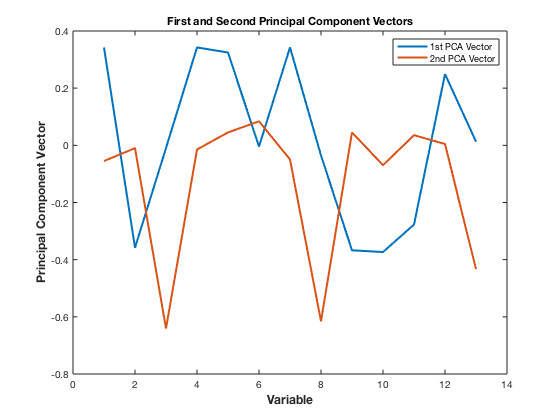

% Plotting the first and the second PCA vectors
figure 
plot(V(:,(1:2)),'LineWidth',2)
title('First and Second Principal Component Vectors')
xlabel('Variable', 'FontSize',12,'FontWeight','bold')
ylabel('Principal Component Vector', 'FontSize',12,'FontWeight','bold')
legend('1st PCA Vector','2nd PCA Vector')
hold off

Fig 1: Min and max loading points of 1st and 2nd PCA vectors 

***Identifying relationships between the variables described by the 2nd principal component vector***

Considering the second principal component vector (Table 2 and Fig 1), it is possible to identify a subset with higher negative loadings of variables (v3 and v8) indicating strong negative relationship. We can also observe a subset with lower positive loadings of variables (v5, v6, v9, v11 and v12) along with a subset of lower negative loadings (v1, v2, v4, v7, v10, and v13) but without any significant connections to the other variables. In conclusion, the second PCA component shows roughly equivalent reliance on “Tuberculosis (cases)” and “Population under 15” (as one increases, so does the other). Both variables have negative sign that means that they are not “inversely” correlated. In addition, the variables with significant negative loadings on 2nd PCA vector are measuring the number of tuberculosis cases in population less than 15 years of age.

***Obtaining singular values and proportions of variation***

We aim to find the components that explain the maximum variance because we want to retain as much information as possible using these components. So, higher is the variance (weights), higher will be the information contained in these components. Weights of the PCA are calculated as square roots of sorted singular values from S matrix. To compute the proportion of variance (weights) by each component in percentage, we simply divide the variance by sum of total variance and multiply by 100. 

% Calculate the weights of the PCA from S matrix
weights = diag(S).^2

weights =   350.2604
  131.4958
   68.4178
   57.5870
   34.0485
   29.7329
   20.7637
   15.3150
   11.2656
    4.6965



% Compute the ratio of each component to the total sum of the weights.
prop_weights = weights / sum(weights) * 100

prop_weights =    48.1127
   18.0626
    9.3981
    7.9103
    4.6770
    4.0842
    2.8522
    2.1037
    1.5475
    0.6451


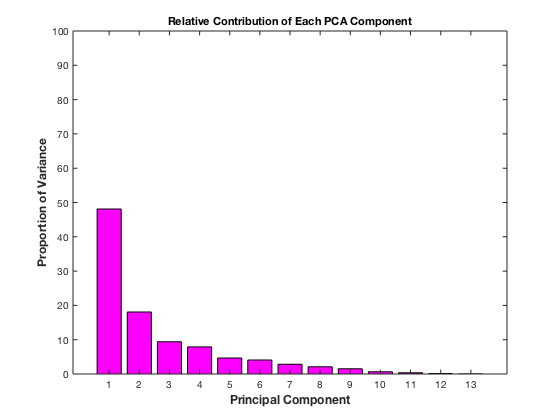


% Create scree plot of the percentage of proportion of variance (variance explained) by each principal component
figure
bar(prop_weights, 'stacked','m') 
ylim([0 100])
title('Relative Contribution of Each PCA Component')
ylabel('Proportion of Variance', 'FontSize',12,'FontWeight','bold')
xlabel('Principal Component', 'FontSize',12,'FontWeight','bold')

Fig 6: Stacked bar plot demonstrates that the 1st PCA component captures the maximum variance (~48.11%) followed by the rest of the components that capture the remaining 

 variance in the dataset in descending order

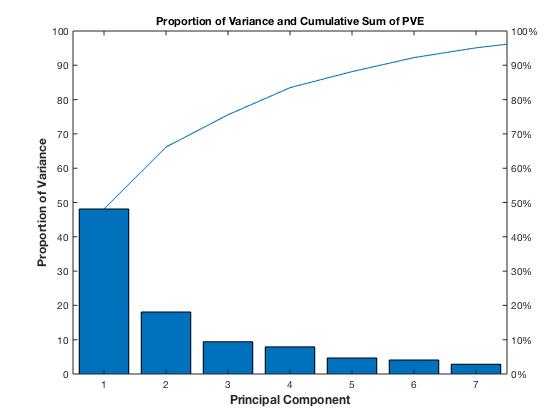

% Create scree plot as a pareto chart
figure
pareto(prop_weights) 
title('Proportion of Variance and Cumulative Sum of PVE')
ylabel('Proportion of Variance', 'FontSize',12,'FontWeight','bold')
xlabel('Principal Component', 'FontSize',12,'FontWeight','bold')

Fig 7: Pareto chart displays relative proportion of variance of seven components in descending order by bars with maximum of variance captured by the 1st PCA component, and the 

          cumulative sum of proportion of total variance up to 95% is represented by the line

The scree plot (Fig 2) is used to graphically present the size of the singular values (eigenvalues) related to each component. We can notice that pareto chart (Fig 3) is showing only first seven PCA components that explains 95% of the total variance. In both graphs (Fig 2 and Fig 3), clear breaks in the amount of variance accounted for by each PCA component are between the 1st and the 2nd PCA components, and maybe between 2nd and 3rd components. In our dataset, the singular values that are presented in the matrix S are used to calculate the proportion of variances due to each component which are given as output of *prop_weights *variable above. The 1stPC component alone accounts for  ~48.11% of the total variance, the 2nd component accounts for 18.1%, the 3rdcomponent accounts for 9.4%, the 4th component accounts for 7.9%, the 5th component accounts for 4.7%, the 6th component accounts for 4.1% and so on. Each succeeding component accounts for progressively smaller amounts of variance. How many components do we need to retain for interpretation of more than 90% of total variance of the original data set? By analyzing the output (*cumprop_weights*variable), we can notice that the first 6 principal components explain 92.24% of the total variance, and the rest of the components up to 13 account for only trivial variance. In order words, we can reduce 13 PCA components to 6 PCA components without compromising on proportion of variance. An alternative criterion that can be used to check the obtained results is to retain enough components so the cumulative sum of proportion of variance explained equals to minimal value (Fig 4).

% % Calculate the cumulative sum of proprtion of variance (variance explained) 
cumprop_weights = cumsum(prop_weights)

cumprop_weights =    48.1127
   66.1753
   75.5734
   83.4837
   88.1607
   92.2448
   95.0970
   97.2007
   98.7482
   99.3933


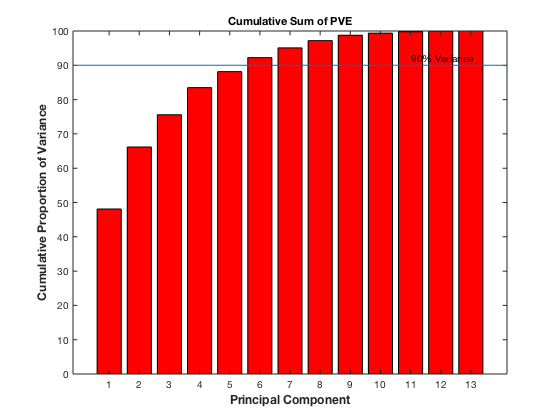

% Create bar plot for cumulative sum of proprtion of variance explained
bar(cumprop_weights, 'stacked', 'r') 
ylim([0 100])
xL = xlim;
line(xL, [90 90]);
title('Cumulative Sum of PVE')
ylabel('Cumulative Proportion of Variance', 'FontSize',12,'FontWeight','bold')
xlabel('Principal Component', 'FontSize',12,'FontWeight','bold')
text(11,92,'90% Variance')

Fig 8: Distribution of cumulative sum of proportion of variance explained (PVE) up to critical point at 90th%

In this study, a critical value for determining the number of components to retain is above 90% (Fig 8). Cumulative sum of proportion of variance explained demonstrates that the cumulative percentage of variance accounted for by components 1, 2, 3, 4, 5 and 6 is 92.24%, as a result, we have to retain all of the first six components. Results of analysis of cumulative sum of proportion of variance explained, as important selective criterion are confirming the findings obtained by very essential criterion assessed previously, both scree plot and percentage of proportion of variance explained.

***The matrix of scores***

% Compute the score matrix of first two principal components
T = U*S(:,1:2)

T =    -2.9141    0.6164
    0.6759    0.7166
   -4.9135    0.7403
   -0.5783    0.4307
   -4.0746    0.7898
   -4.9781   -0.7145
   -2.1105    0.3948
    2.1833    0.8897
   -1.9972    0.8198
   -0.0372    0.3201


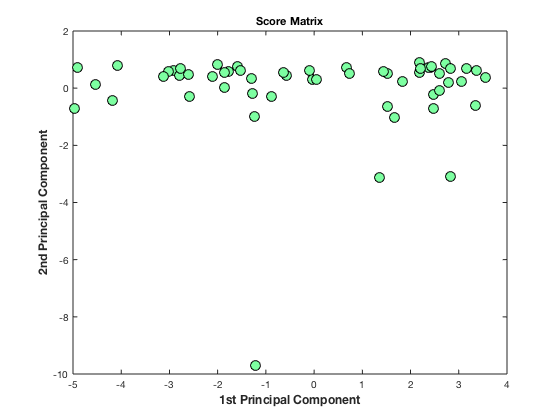

% Plot the 1st and 2nd PCA components of the score matrix
figure
plot(T(:,1),T(:,2), 'ok', 'MarkerEdgeColor', 'k', 'MarkerFaceColor',[.49 1 .63], 'MarkerSize',10)
title('Score Matrix')
xlabel('1st Principal Component', 'FontSize',12, 'FontWeight', 'bold')
ylabel('2nd Principal Component', 'FontSize',12, 'FontWeight', 'bold')

Fig 5: Score matrix displays the mean-centered and scaled data projected onto the first two principal components 

% Read in the input dataset as a tablein order to connect Country variable to PCA components  
country_data = readtable("SotTCombined2010.xlsx")

country_data = 109×14 table
                  Country                   LifeExpectancy_years_    PovertyUnder_1_25PerDay    PopulationUnder15    AdultLiteracy__Above15_    MeanYearsOfSchooling    Unemployment___    YouthLiteracy__Age15_24_    Tuberculosis_cases_    Under5Mortality_underAge5Per1000Births_    PovertyUnder_2PerDay    Undernourishment    UrbanPopulation___    AreaOfAgriculturalLand____
    ____________________________________    _____________________    _______________________    _________________    _______________________    ____________________    _______________    ________________________    _

% Perform the same pre-processing steps because dimensions have to be the same
% Remove missing values from the dataset
country_datarm = rmmissing(country_data)

country_datarm = 56×14 table
                  Country                   LifeExpectancy_years_    PovertyUnder_1_25PerDay    PopulationUnder15    AdultLiteracy__Above15_    MeanYearsOfSchooling    Unemployment___    YouthLiteracy__Age15_24_    Tuberculosis_cases_    Under5Mortality_underAge5Per1000Births_    PovertyUnder_2PerDay    Undernourishment    UrbanPopulation___    AreaOfAgriculturalLand____
    ____________________________________    _____________________    _______________________    _________________    _______________________    ____________________    _______________    ________________________    

% Extract the first Country column from the modified input data set
country_datarm = country_datarm(:,1)

country_datarm = 56×1 table
                  Country               
    ____________________________________

    {'Benin'                           }
    {'Botswana'                        }
    {'Burundi'                         }
    {'Cameroon'                        }
    {'Central African Republic'        }
    {'Democratic Republic of the Congo'}
    {'Cote d'Ivoire'                   }
    {'Gabon'                           }
    {'Gambia'                          }
    {'Ghana'                           }
    {'Kenya'                           }
    {'Liberia'                         }
    {'Malawi'                          }
    {'Mozambique'                      }
    {'Namibia'                         }
    {'Rwanda'                          }


% Convert the frist two columns of score matrix into table
T_country = array2table(T)

T_country = 56×2 table
       T1           T2   
    _________    ________

      -2.9141     0.61644
      0.67589      0.7166
      -4.9135     0.74027
     -0.57835     0.43067
      -4.0746     0.78978
      -4.9781    -0.71453
      -2.1105     0.39478
       2.1833     0.88968
      -1.9972     0.81978
    -0.037245     0.32009
     -0.87954    -0.29131
      -3.0295     0.59469
      -2.7977     0.45842
      -4.1873    -0.42989
    -0.089585       0.608
      -2.6078     0.48015


% Concatenate table T_country and table country_datarm  
T_country = [country_datarm T_country]

T_country = 56×3 table
                  Country                      T1           T2   
    ____________________________________    _________    ________

    {'Benin'                           }      -2.9141     0.61644
    {'Botswana'                        }      0.67589      0.7166
    {'Burundi'                         }      -4.9135     0.74027
    {'Cameroon'                        }     -0.57835     0.43067
    {'Central African Republic'        }      -4.0746     0.78978
    {'Democratic Republic of the Congo'}      -4.9781    -0.71453
    {'Cote d'Ivoire'                   }      -2.1105     0.39478
    {'Gabon'                           }       2.1833     0.88968
    {'Gambia'                          }      -1.9972     0.81978
    {'Ghana'                           }    -0.037245     0.32009
    {'Kenya'                           }     -0.87954    -0.29131
    {'Liberia'  

% Calculating the min values for 1st PCA component
minValue1 = sortrows(T_country,'T1')

minValue1 = 56×3 table
                  Country                     T1          T2   
    ____________________________________    _______    ________

    {'Democratic Republic of the Congo'}    -4.9781    -0.71453
    {'Burundi'                         }    -4.9135     0.74027
    {'Niger'                           }    -4.5333     0.13209
    {'Mozambique'                      }    -4.1873    -0.42989
    {'Central African Republic'        }    -4.0746     0.78978
    {'Zambia'                          }    -3.1282     0.40198
    {'Liberia'                         }    -3.0295     0.59469
    {'Benin'                           }    -2.9141     0.61644
    {'Malawi'                          }    -2.7977     0.45842
    {'Haiti'                           }    -2.7707     0.67559
    {'Rwanda'                          }    -2.6078     0.48015
    {'Tanzania'                        }  

% Display of first three countries related to the first three minimal values of 1st PCA component
smallest1 = minValue1([1 2 3],:)

smallest1 = 3×3 table
                  Country                     T1          T2   
    ____________________________________    _______    ________

    {'Democratic Republic of the Congo'}    -4.9781    -0.71453
    {'Burundi'                         }    -4.9135     0.74027
    {'Niger'                           }    -4.5333     0.13209


% Calculating the min values for 2st PCA component
minValue2 = sortrows(T_country,'T2')

minValue2 = 56×3 table
                  Country                      T1          T2    
    ____________________________________    ________    _________

    {'India'                           }     -1.2111      -9.7036
    {'Indonesia'                       }      1.3585      -3.1258
    {'Brazil'                          }      2.8297      -3.1061
    {'Philippines'                     }      1.6575      -1.0122
    {'Sudan'                           }     -1.2355     -0.98739
    {'Democratic Republic of the Congo'}     -4.9781     -0.71453
    {'China'                           }      2.4684     -0.70714
    {'Vietnam'                         }       1.531     -0.65446
    {'Mexico'                          }      3.3368     -0.61376
    {'Mozambique'                      }     -4.1873     -0.42989
    {'Tanzania'                        }     -2.5783     -0.30869
    {'Kenya'    

% Display of first three countries related to the first three minimal values of 2nd PCA component
smallest2 = minValue2([1 2 3],:)

smallest2 = 3×3 table
       Country         T1         T2   
    _____________    _______    _______

    {'India'    }    -1.2111    -9.7036
    {'Indonesia'}     1.3585    -3.1258
    {'Brazil'   }     2.8297    -3.1061


% Display of first three countries related to the first three maximal values of 1st PCA component
largest1 = minValue1([end end-1 end-2],:)

largest1 = 3×3 table
       Country          T1         T2   
    ______________    ______    ________

    {'Malaysia'  }    3.5616     0.35892
    {'Costa Rica'}    3.3584     0.61922
    {'Mexico'    }    3.3368    -0.61376


% Display of first three countries related to the first three maximal values of 2nd PCA component
largest2 = minValue2([end end-1 end-2],:)

largest2 = 3×3 table
      Country        T1         T2   
    ___________    _______    _______

    {'Gabon'  }     2.1833    0.88968
    {'Jamaica'}      2.721    0.84708
    {'Gambia' }    -1.9972    0.81978


The matrix of scores (T) is the same size as the input data matrix and contains the coordinates of the original data projected in the new coordinate system defined by the principal components. From (Fig 5) by examining magnitude of values in the score matrix shown in the output as minimum and maximum values, Malaysia country has the highest score (3.5616) on the 1st component. This is reasonable, considering its dynamic economic and social progress lifted millions of people out of poverty and educational inequality. While on 2nd component, India, Indonesia and Brasil have highest magnitude on y axis of (-9.7036, -3.1258, -3.1061) respectively with negative signs which means that they are not "inversely'' correlated. These countries can be viewed as extreme countries for 2nd PCA component that interprets India is leading the count, followed by Indonesia in number of people (cases) infected with bacteria *Mycobacterium tuberculosis* and number of children infected under the age of 15. On the other hand, if we observe carefully the score matrix (Fig 5), we can notice that India, Brasil and Indonesia are located at a distance from the amount of the data distribution; as a result, they can be observed as large score matrix outliers. If we eliminate them as outliers, then, the next country with the highest magnitude on y-axis is Philippines.

The minimum values on 1st component is observed at Democratic Republic of Congo (-4.9781), Burundi (-4.9135) and Niger (-4.5333) which means that these countries have the lowest level of Life Expectancy, Adult and Youth Literacy or the lowest economic and social progress. Since, the 1st component accounts for the most variation in the dataset, general highest and lowest levels are obtained from 1st PCA component. In general, we can confirm that Malaysia is the most rapid growing country and The Democratic Republic of Congo is the slowest growing country.

***A dimensionally reduced representation of the dataset***

% Compute the reduced matrix from only first six PCA components
reduced = U * S(:,1:6) * V(:,1:6)'

reduced =    -0.7820    0.5781   -0.2929   -2.0736   -1.4213   -1.1012   -2.0920   -0.2608    1.2255    0.7804   -0.6912   -0.0387   -0.6406
   -0.5772    0.1274   -0.4048    0.6667    0.9325    1.6614    0.6723   -0.3604    0.1410   -0.2076    0.5835    1.1406   -0.0449
   -1.8073    2.4355   -0.5364   -0.5179   -0.9397   -0.1963   -0.5526   -0.3693    1.6509    2.1659    3.0844   -1.9986   -0.2145
   -0.4263    0.2105   -0.1957   -0.5412   -0.0523   -0.2393   -0.5394   -0.1817    0.4654    0.1295   -0.2536    0.6991   -0.3548
   -1.7258    1.5743   -0.3956   -1.5823   -1.0316   -0.1200   -1.5912   -0.2758    1.7840    1.4624    0.9715   -0.1421   -0.5285
   -2.1251    2.3353    0.5447   -1.2211   -0.9432   -0.2310   -1.1755    0.6726    2.0224    2.1216    2.1174   -0.5642    0.1764
   -0.8712    0.5885   -0.2379   -1.3145   -0.8095   -0.3362   -1.3167   -0.2729    1.0579    0.5726   -0.1069    0.4890   -0.0141
    0.0092   -0.7734   -0.4421    0.4652    1.1083    1.4746    0.4710   

***The residuals of the reduced representation***

% Compute the residuals/SPE. This is the difference between X_scaled and matrix reduced. 
% Residuals aid in identifying the outliers in the given data. 

SPE = sum((X_scaled - reduced).^2,2)

SPE =     0.3005
    2.9998
    1.3416
    2.9228
    0.5057
    1.2764
    1.5974
    0.9108
    0.3353
    0.9161



% Convert SPE into table
spe_country = array2table(SPE)

spe_country = 56×1 table
      SPE  
    _______

     0.3005
     2.9998
     1.3416
     2.9228
    0.50567
     1.2764
     1.5974
    0.91075
    0.33526
    0.91607
    0.73951
     2.3086
     2.4741
    0.67972
    0.30338
     0.7083


% Concatenate table spe_country and table country_datarm (previously created above)
spe_country = [country_datarm spe_country]

spe_country = 56×2 table
                  Country                     SPE  
    ____________________________________    _______

    {'Benin'                           }     0.3005
    {'Botswana'                        }     2.9998
    {'Burundi'                         }     1.3416
    {'Cameroon'                        }     2.9228
    {'Central African Republic'        }    0.50567
    {'Democratic Republic of the Congo'}     1.2764
    {'Cote d'Ivoire'                   }     1.5974
    {'Gabon'                           }    0.91075
    {'Gambia'                          }    0.33526
    {'Ghana'                           }    0.91607
    {'Kenya'                           }    0.73951
    {'Liberia'                         }     2.3086
    {'Malawi'                          }     2.4741
    {'Mozambique'                      }    0.67972
    {'Namibia'                         }    0.30338
    {'Rwanda'         

% Remove outliers with quartiles from SPE
[SPERO,TF] = rmoutliers(SPE,'quartiles')

SPERO =     0.3005
    1.3416
    0.5057
    1.2764
    1.5974
    0.9108
    0.3353
    0.9161
    0.7395
    2.3086


TF = 56×1 logical array
   0
   1
   0
   1
   0
   0
   0
   0
   0
   0


% Create table for Outliers
Outlier = array2table(TF)

Outlier = 56×1 table
     TF  
    _____

    false
    true 
    false
    true 
    false
    false
    false
    false
    false
    false
    false
    false
    false
    false
    false
    false


% Concatenate table Outliers with table spe_country
Outlier = [spe_country Outlier]

Outlier = 56×3 table
                  Country                     SPE       TF  
    ____________________________________    _______    _____

    {'Benin'                           }     0.3005    false
    {'Botswana'                        }     2.9998    true 
    {'Burundi'                         }     1.3416    false
    {'Cameroon'                        }     2.9228    true 
    {'Central African Republic'        }    0.50567    false
    {'Democratic Republic of the Congo'}     1.2764    false
    {'Cote d'Ivoire'                   }     1.5974    false
    {'Gabon'                           }    0.91075    false
    {'Gambia'                          }    0.33526    false
    {'Ghana'                           }    0.91607    false
    {'Kenya'                           }    0.73951    false
    {'Liberia'                         }     2.3086    false
    {'Malawi'         

% Filter Outliers
Outlier(Outlier.TF==1,:)

ans = 4×3 table
       Country        SPE       TF  
    _____________    ______    _____

    {'Botswana' }    2.9998    true 
    {'Cameroon' }    2.9228    true 
    {'Haiti'    }    3.4688    true 
    {'Guatemala'}    2.9571    true 


Residuals or SPE (square prediction error) or reconstruction error presents deviation between the reconstructed/reduced data and the original data. It is actually square distance between the original data and the reconstructed data and it is inversely proportional to the total variance of the PCA space. If we select a larger number of components, the variation of lower PCA space will increase and the error between the reconstructed data and the original data will decrease. However, the robustness of PCA is measured by the ratio between the total variance of PCA to the total variance of original data. PCA is very sensitive to pre-processing the data and to outliers. If an observation has a large SPE, then we say this observation is inconsistent within the dataset. PCA components reconstruct the original dataset and provide a correlation structure between the variables in the dataset. When an observation has a large SPE, then that observation is destroying the correlation structure, thus it is inconsistent for the model of PCA. The aim of PCA is dimension reduction that means to explain as much variability (variance) as possible with only a few PCA components. If the data has some underlying data points, the dimension can almost always be reduced. Large outliers increase the non-robustness of PCA or decrease the variation of PCA space. As shown by PCA, there are two types of outliers: large score matrix outliers and residual outliers. Four data points obtained as residual outliers are related to Bostwana, Cameroon, Haiti and Guatemala. Score matrix outliers are India, Brazil and Indonesia as shown on (Fig 5). 

% Identifying outliers from the score matrix
% Outliers from the 1st PCA component
[PCA1_out, TF1] = rmoutliers(T(:,1), 'quartile') 

PCA1_out =    -2.9141
    0.6759
   -4.9135
   -0.5783
   -4.0746
   -4.9781
   -2.1105
    2.1833
   -1.9972
   -0.0372


TF1 = 56×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


% Outliers from the 2nd PCA component
[PCA2_out, TF2] = rmoutliers(T(:,2), 'quartile') 

PCA2_out =     0.6164
    0.7166
    0.7403
    0.4307
    0.7898
   -0.7145
    0.3948
    0.8897
    0.8198
    0.3201


TF2 = 56×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


TF1 = array2table(TF1)

TF1 = 56×1 table
     TF1 
    _____

    false
    false
    false
    false
    false
    false
    false
    false
    false
    false
    false
    false
    false
    false
    false
    false


TF2 = array2table(TF2) 

TF2 = 56×1 table
     TF2 
    _____

    false
    false
    false
    false
    false
    false
    false
    false
    false
    false
    false
    false
    false
    false
    false
    false


TF2_Outliers = [country_datarm TF2]

TF2_Outliers = 56×2 table
                  Country                    TF2 
    ____________________________________    _____

    {'Benin'                           }    false
    {'Botswana'                        }    false
    {'Burundi'                         }    false
    {'Cameroon'                        }    false
    {'Central African Republic'        }    false
    {'Democratic Republic of the Congo'}    false
    {'Cote d'Ivoire'                   }    false
    {'Gabon'                           }    false
    {'Gambia'                          }    false
    {'Ghana'                           }    false
    {'Kenya'                           }    false
    {'Liberia'                         }    false
    {'Malawi'                          }    false
    {'Mozambique'                      }    false
    {'Namibia'                         }    false
    {'Rwanda'                          }    false


TF2_Outliers(TF2_Outliers.TF2==1,:)

ans = 3×2 table
       Country        TF2 
    _____________    _____

    {'India'    }    true 
    {'Indonesia'}    true 
    {'Brazil'   }    true 
